pressure1a = importdata('pressure1a.txt');
pressure1b = importdata('pressure1b.txt');

parameterized = ([1:(15001-2)]).*0.004;

pump_pressure1a = pressure1a(3:end,1);
total_pressure1a = pressure1a(3:end,2);

pump_pressure1b = pressure1b(3:end,1);
total_pressure1b = pressure1b(3:end,2);

ts_pump_pressure1a = timeseries(pump_pressure1a, parameterized);
ts_total_pressure1a = timeseries(total_pressure1a, parameterized);

ts_pump_pressure1b = timeseries(pump_pressure1b, parameterized);
ts_total_pressure1b = timeseries(total_pressure1b, parameterized);

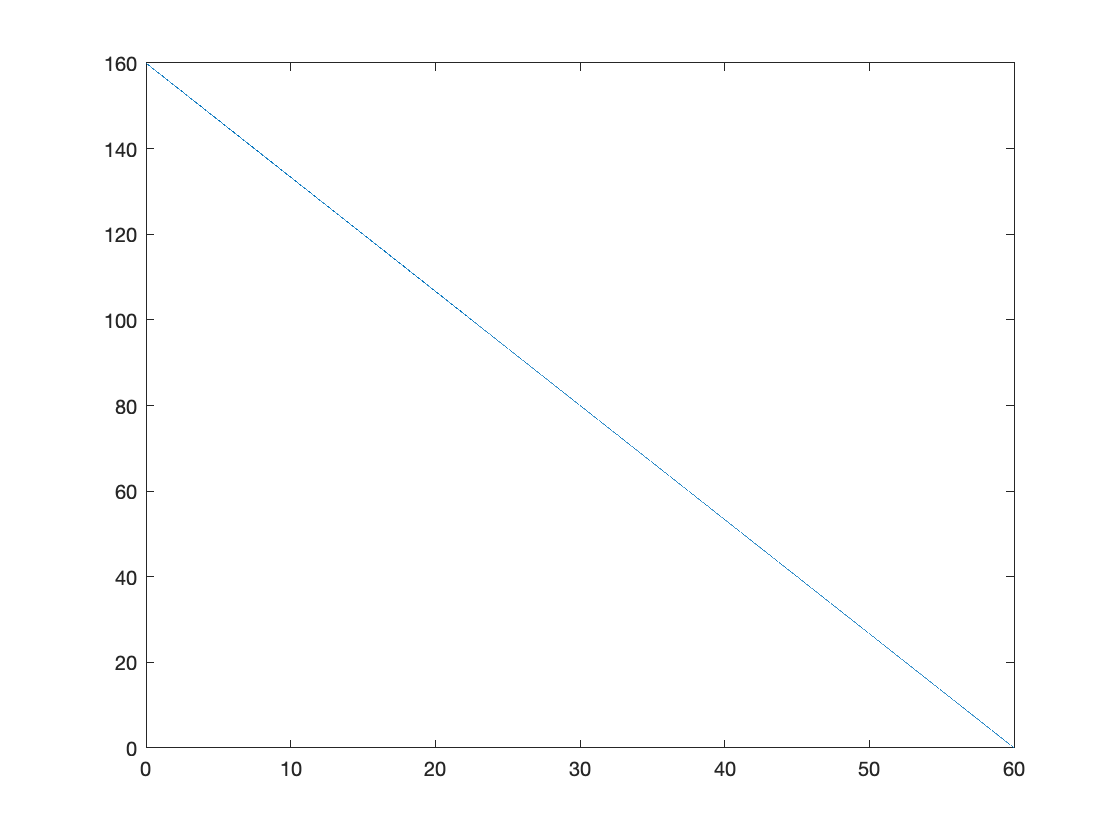

plot(parameterized, pump_pressure1a);

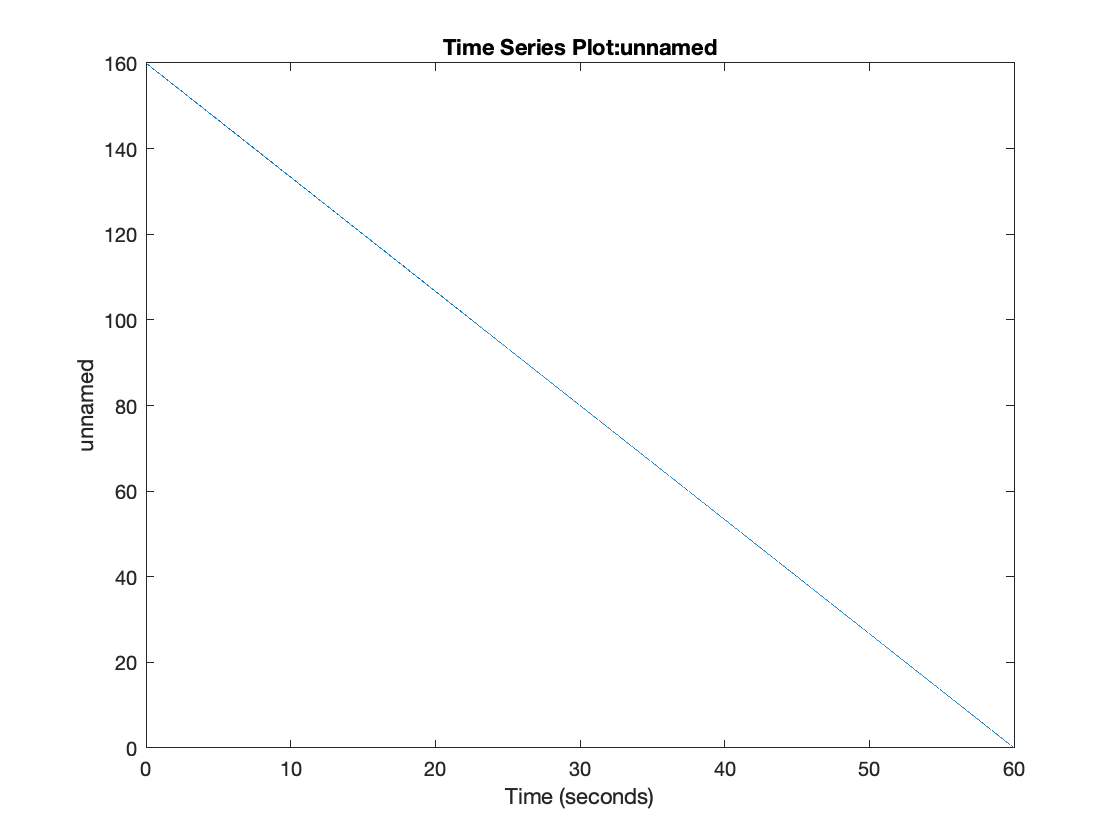

plot(ts_pump_pressure1a);

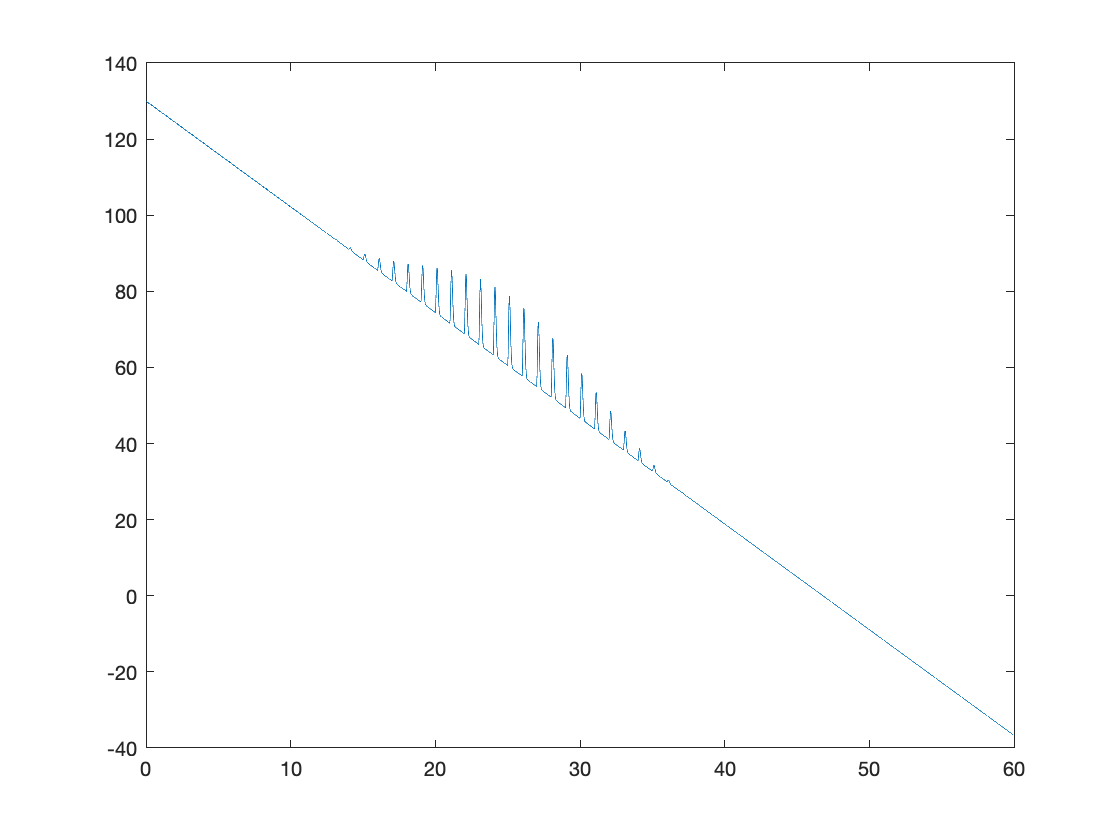

plot(parameterized, total_pressure1a);

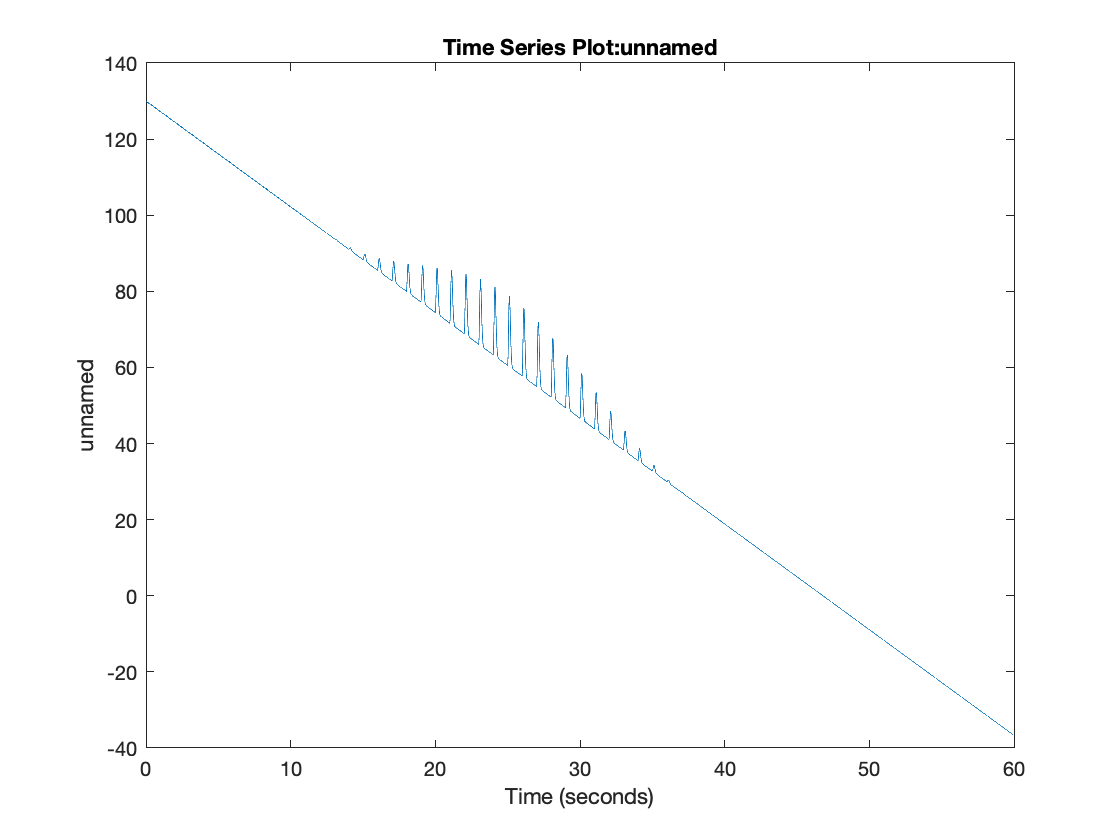

plot(ts_total_pressure1a);

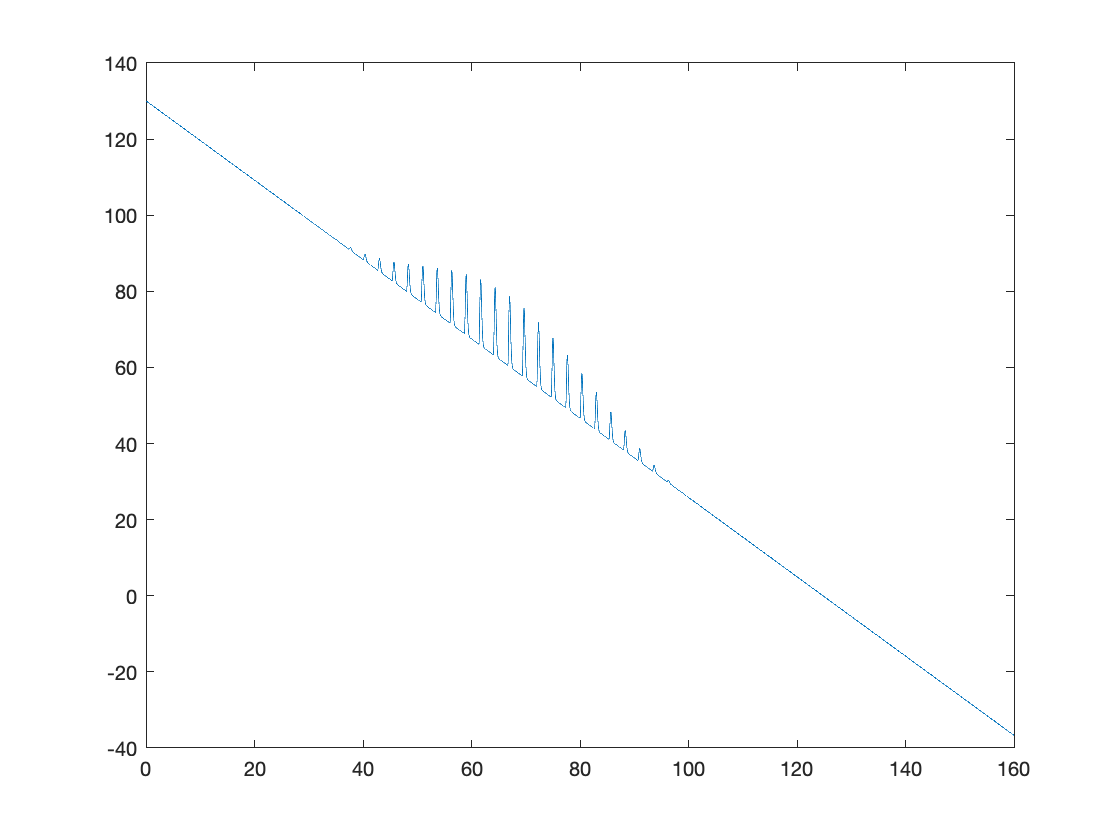

plot(flip(pump_pressure1a), total_pressure1a);

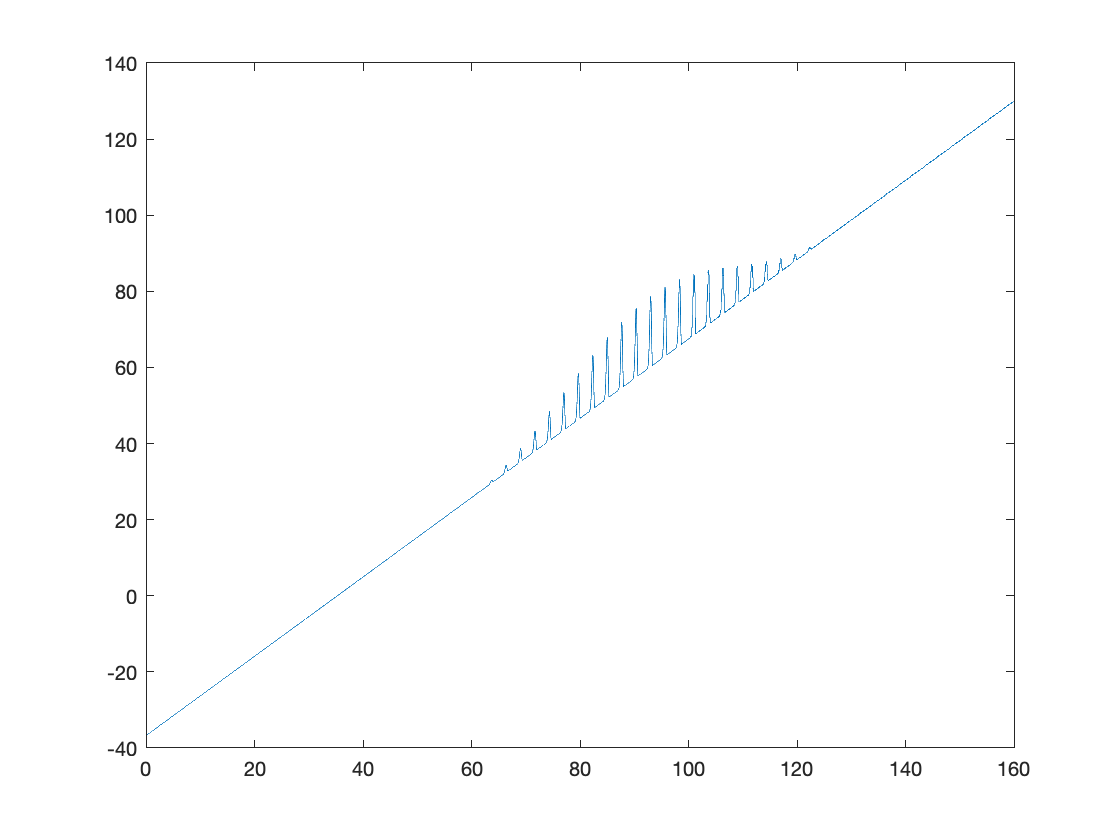

plot(pump_pressure1a, total_pressure1a);

save('blood_pressure_signals',...
    "ts_pump_pressure1a","ts_total_pressure1a","ts_pump_pressure1b",...
    "ts_total_pressure1b","pump_pressure1a","total_pressure1a",...
    "pump_pressure1b","total_pressure1b");